## STAT Opsummerende Problem

clear, close all, clc;

data = xlsread('expected_lifetimes.xlsx');
opengl hardware;

Del 1: Modeltjek

Indledningsvis anvendes kun data fra 2011/2012. Lav en vektor med data for mændenes gennemsnitslevealder i alle regioner.

Y = data(2:12,12);
n = length(Y);

Dette antages at være en stikprøve af en normalfordelt population med ukendt middelværdi og varians.

Plot værdierne langs en akse. Lav et boksplot. Lav et QQ-plot. Konkluder på antagelserne om populationen.

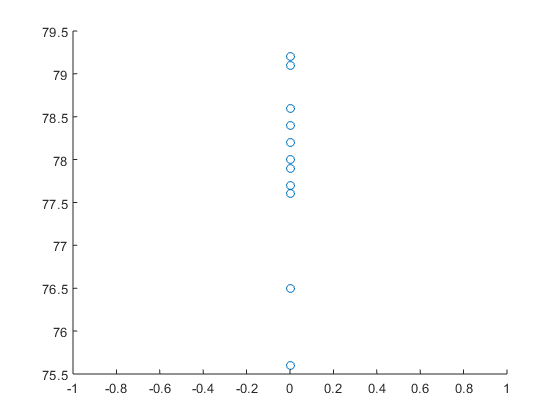

null = [0;0;0;0;0;0;0;0;0;0;0];

scatter(null,Y)

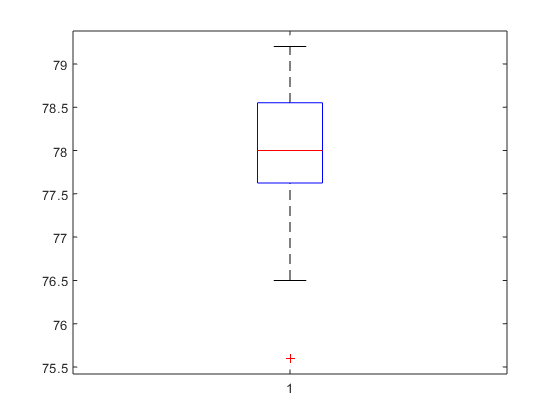

boxplot(Y)

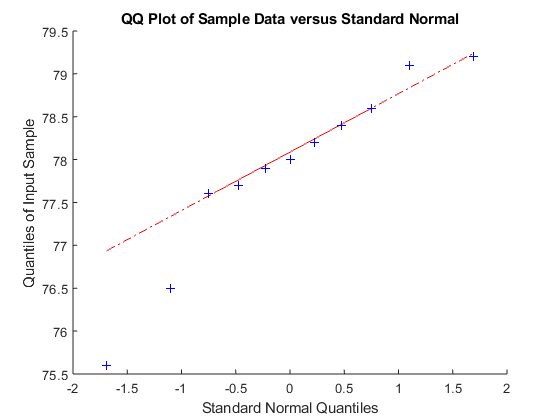

qqplot(Y)

Antagelsen er nogenlunde korrekt, med rimelig afvigelse i den lave ende af sitkprøven. Grundet de få observationer er dette tilnærmelsesvis normalfordelt.

Lav en vektor for kvindernes gennemsnitslevealder i alle regioner. Lav ligeledes samme antagelser og plots, og konkluder på disse plots.

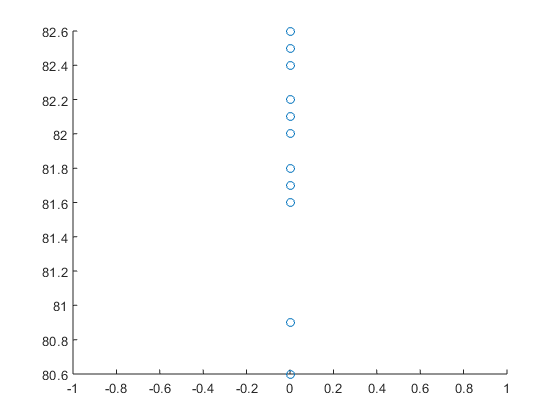

X = data(14:24,12);
scatter(null,X)

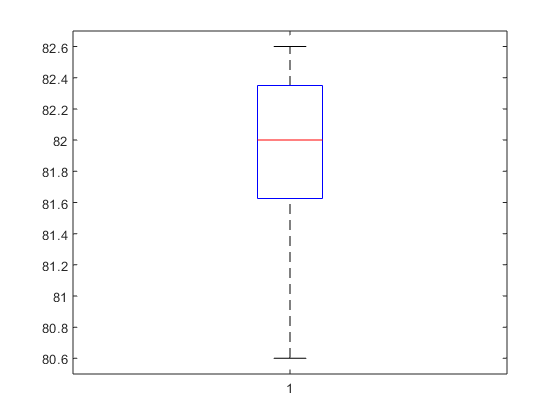

boxplot(X)

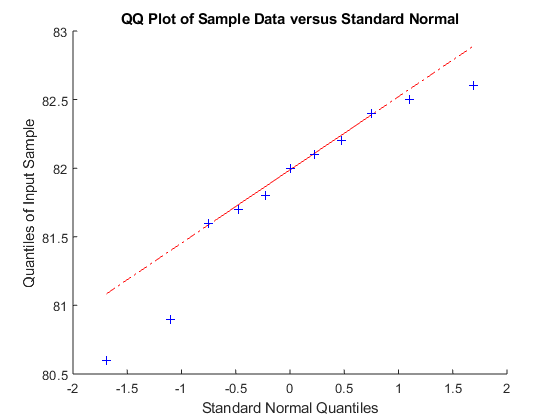

qqplot(X)

Her er ligeledes store afvigelser i bunden, men også lidt i toppen. Igen antages det dog, at den er normalfordelt, grundet de få observationer.

Del 2: Parameterestimater, stikprøvefordeling, konfidensintervaller

Giv ikke-biased estimatorer for de ukendte parametre, middelværdi og varians, for begge stikprøver. Udregn parametrene med vektorerne X og Y.

% X_bar = sum(Xi)/n
% s^2_x = sum(Xi-X_bar)^2/(n-1)
X_bar = mean(X)

X_bar = 81.8545

Y_bar = mean(Y)

Y_bar = 77.8909

s_x = std(X)

s_x = 0.6362

s_y = std(Y)

s_y = 1.0653

s_x_squared = var(X)

s_x_squared = 0.4047

s_y_squared = var(Y)

s_y_squared = 1.1349

Angiv stikprøvefordelingen for alle estimatorer:

X_bar ~ N(mu_x , sigma_x/n)

Y_bar ~ N(mu_y , sigma_y/n)

s_x_squared ~ Chi^2(n-1) * (sigma^2_x/(n-1))

s_y_squared ~ Chi^2(n-1) * (sigma^2_y/(n-1))

Udregn et tosidet konfidensinterval på 90%, 95% og 99% for den ukendte middelværdi både for X og Y.

% Kvinder, 90% - 95% - 99%
L_X90 = X_bar + tinv(0.1/2,n-1) * s_x/sqrt(n)

L_X90 = 81.5069

U_X90 = X_bar + tinv(1-0.1/2,n-1) * s_x/sqrt(n)

U_X90 = 82.2022

L_X95 = X_bar + tinv(0.05/2,n-1) * s_x/sqrt(n)

L_X95 = 81.4272

U_X95 = X_bar + tinv(1-0.05/2,n-1) * s_x/sqrt(n)

U_X95 = 82.2819

L_X99 = X_bar + tinv(0.01/2,n-1) * s_x/sqrt(n)

L_X99 = 81.2466

U_X99 = X_bar + tinv(1-0.01/2,n-1) * s_x/sqrt(n)

U_X99 = 82.4625


% Mænd, 90% - 95% - 99%
L_Y90 = Y_bar + tinv(0.1/2,n-1) * s_y/sqrt(n)

L_Y90 = 77.3087

U_Y90 = Y_bar + tinv(1-0.1/2,n-1) * s_y/sqrt(n)

U_Y90 = 78.4731

L_Y95 = Y_bar + tinv(0.05/2,n-1) * s_y/sqrt(n)

L_Y95 = 77.1752

U_Y95 = Y_bar + tinv(1-0.05/2,n-1) * s_y/sqrt(n)

U_Y95 = 78.6066

L_Y99 = Y_bar + tinv(0.01/2,n-1) * s_y/sqrt(n)

L_Y99 = 76.8729

U_Y99 = Y_bar + tinv(1-0.01/2,n-1) * s_y/sqrt(n)

U_Y99 = 78.9089

Del 3: Hypotesetest af en stikprøve

Lav en tosidet hypotesetest af den mandlige population med nulhypotesen: mu_y = 77.

Definer først test-statistik, indiker fordelingen hvis H0 er korrekt, udregn test-statistikkens værdi, udfør testen med alpha = [0.1 0.05 0.01], og udregn p-værdien.

Udregn dernæst power som funktion af den ukendte middelværdi, og konkluder på det hele.

% Test-statistik:
% T0 = (Y_bar - mu_y) / (s_y / sqrt(n)) ~ t_n-1
% Fordeling:
% ~ N (77, sigma_y^2)
% Udregn:
mu_y = 77;
t0_y = (Y_bar - mu_y) / (s_y / sqrt(n))

t0_y = 2.7736

alpha = [0.1 0.05 0.01];
crit_val_y = tinv(1-alpha/2,n-1)

crit_val_y =     1.8125    2.2281    3.1693


%downquart_y = tinv(alpha/2,n-1)
%HUSK AT TJEKKE NEDRE VÆRDIER

% Nulhypotesen kan altså forkastes ved 0.1 og 0.05,
% men ikke med et signifikansniveau på 0.01.

p = 2 * (1 - tcdf(t0_y,n-1))

p = 0.0197

% Det samme bekræftes at p-værdien, der er knap 0.02.

% Power udregnes nu for én værdi:
% Dette skal gentages for alle værdier, f.eks.
% med et loop eller stor vektor
pwr = sampsizepwr('t',[Y_bar s_y],mu_y,[],n)

pwr = 0.7058


% Alternativ udregning af power:
mu_x_vals = 75:0.01:80;
beta_y_vals = tcdf((mu_y - mu_x_vals')/sqrt(s_y^2/n)*ones(1,3) + ones(501,1)*tinv(1-alpha/2,n-1),n-1) - ... 
                     tcdf((mu_y - mu_x_vals')/sqrt(s_y^2/n)*ones(1,3) - ones(501,1)*tinv(1-alpha/2,n-1),n-1);
power_y_vals = 1 - beta_y_vals;

Lav dernæst en tosidet hypotesetest af den kvindelige population med nulhypotesen: mu_x = 81.

Definer først test-statistik, indiker fordelingen hvis H0 er korrekt, udregn test-statistikkens værdi, udfør testen med alpha = [0.1 0.05 0.01], og udregn p-værdien.

Udregn dernæst power som funktion af den ukendte middelværdi, og konkluder på det hele.

% Test-statistik:
% T0 = (X_bar - mu_x) / (s_x / sqrt(n)) ~ t_n-1
% Fordeling:
% ~ N (81, sigma_x^2)
% Udregn:
mu_x = 81;
t0_x = (X_bar - mu_x)/(s_y/sqrt(n))

t0_x = 2.6604

crit_val_x = tinv(1-alpha/2,n-1)

crit_val_x =     1.8125    2.2281    3.1693


%HUSK AT TJEKKE NEDRE VÆRDIER
% Testen indikerer altså, at nulhypotesen med en
% alpha-værdi på 0.1 eller 0.05 forkastes.
% Dog kan den ikke forkastes med 0.01 siginifikansniveau.

p = 2 * (1 - tcdf(t0_x,n-1))

p = 0.0239

% p-værdien viser altså det samme.

% Udregning af power:
mu_x_vals = 79:0.01:83;
beta_x_vals = tcdf((mu_x - mu_x_vals')/sqrt(s_x^2/n)*ones(1,3) + ones(401,1)*tinv(1-alpha/2,n-1),n-1) - ... 
                     tcdf((mu_x - mu_x_vals')/sqrt(s_x^2/n)*ones(1,3) - ones(401,1)*tinv(1-alpha/2,n-1),n-1);
power_x_vals = 1 - beta_x_vals;

Del 4: To-sample hypotesetest

Lav en to-sidet hypotesetest med nulhypotesen H0: sigma_x = sigma_y, altså at varianserne er identiske. Gør dette ved at definere test-statistik, indikere dens fordeling ved sand H0, udregne test-statistikkens værdi, teste med alpha = 0.1, 0.05 og 0.01, og udregne p-værdien for testen. Konkluder på dette.

Hvis H0 ikke kan forkastes, udregn da et pooled estimat af den fælles varians.

% Test-statistik:
% F0 = s_1^2 / s_2^2 ~ F_(n_1-1,n_2-1)
% Fordeling:
% ~ N(mu,sigma^2)
% Udregn:
f0 = s_y_squared / s_x_squared

f0 = 2.8041

crit_val = finv(1-alpha/2,n-1,n-1)

crit_val =     2.9782    3.7168    5.8467


%HUSK AT TJEKKE NEDRE VÆRDIER
% Testen indikerer altså, at nulhypotesen ikke kan
% forkastes ved noget signifikansniveau.

p = 2 * (1 - fcdf(f0,n-1,n-1))

p = 0.1193

% Dette viser p-værdien også.

% Pooled estimat:
s_p_squared = ((n-1)*s_y_squared + (n-1)*s_x_squared)/(n+n-2)

s_p_squared = 0.7698

Lav en ensidet hypotesetest, hvor H0: mu_x - 3 =< mu_y (mu_x-mu_y = 3), altså mu_x er 3 eller færre år større end mu_y. Gør dette ved at definere test-statistik, indikere dens fordeling hvis H0 sand, udregne test-statstikkens værdi, udføre testen med alpha = 0.1, 0.05, 0.01 og udregne p-værdien.

% Test-statistik:
% ((X_bar - Y_bar) - Delta_0) / (s_p_squared * sqrt(1/n + 1/n)
% ~ t_n+n-2
% Fordeling:
% ~ N(mu,sigma^2)
% Udregn:
Delta_0 = 3

Delta_0 = 3

t0 = ((X_bar - Y_bar) - Delta_0) / (sqrt(s_p_squared*(1/n+1/n)))

t0 = 2.5757

crit_val = tinv(1-alpha,n+n-2)

crit_val =     1.3253    1.7247    2.5280


% Det ses altså, at nulhypotesen forkastes i alle tilfælde

p = (1 - tcdf(t0,n+n-2))

p = 0.0090

% Det samme viser p-værdien

Udreng forskellen mellem de mandlige og kvindelige levetider i alle 11 regioner. Lav en ensidet, parret hypotesetest, hvor H0: mu_x - 3 =< mu_y (mu_x - mu_y = 3). Definer først test-statistik, indiker dens fordeling hvis H0 er sand, og udregn dens værdi. Udfør testen med alpha = 0.1, 0.05, 0.01 og udregn p-værdien. Sammenlign med den ikke-parrede test.

% Test-statistik:
% T0 = (D_bar - Delta_0) / (s_D / sqrt(n)) ~ t_n-1
% Fordeling:
% ~ N(mu,sigma^2)
% Udregning:
D_2012 = X - Y;
D_bar = mean(D_2012)

D_bar = 3.9636

s_D = std(D_2012)

s_D = 0.5182

s_D_squared = var(D_2012)

s_D_squared = 0.2685

t0 = (D_bar - Delta_0) / (s_D/sqrt(n))

t0 = 6.1674

crit_val = tinv(1-alpha,n-1)

crit_val =     1.3722    1.8125    2.7638


% Nulhypotesen forkastes altså i alle tilfælde
p = (1 - tcdf(t0,n-1))

p = 5.2940e-05


% Det er altså meget mere usandsynligt i den parrede test

Del 5: Simpel lineær regression: estimering af parametre og modelkontrol

I denne og næste del bruges nyt data fra excel-arket. Der anvendes det nationale gennemsnit fra år 2000/2001 til 2011/2012.

Lav en vektor med data for mænd.

Y_nat = data(1,1:12)';
n_nat = length(Y_nat)

n_nat = 12

t = 1:12;

Vis den simple lineære regressionsmodel, hvor normalfordelte residualer antages.

% Levealder = Beta_0 + Beta_1 * Årstal efter 2000 + epsilon_i

Estimer de ukendte parametre i modellen: Skæring med y-aksen (Beta_0), hældning (Beta_1) og varians af fejlled.

Y_reg = [[1:12]' ones(size(Y_nat))];
[b, bint, r, rint, STATS] = regress(Y_nat, Y_reg);
Beta_0_y = b(2)

Beta_0_y = 74.0121

Beta_1_y = b(1)

Beta_1_y = 0.3007

% Varians af fejlled: SSE/df
% Findes med STATS(4)
sigma_e_squared_y = STATS(4)

sigma_e_squared_y = 0.0257

sigma_e_y = sqrt(sigma_e_squared_y)

sigma_e_y = 0.1602

Find R^2

% R^2 = STATS(1)
R2 = STATS(1)

R2 = 0.9805

Plot observationerne sammen med den estimerede regressionslinje

scatter(t,Y_nat)
hold on
t_est = 1:0.01:13;
Y_est = Beta_0_y + Beta_1_y * t_est;
plot(t_est,Y_est)

Lav modeltjek for residualerne:

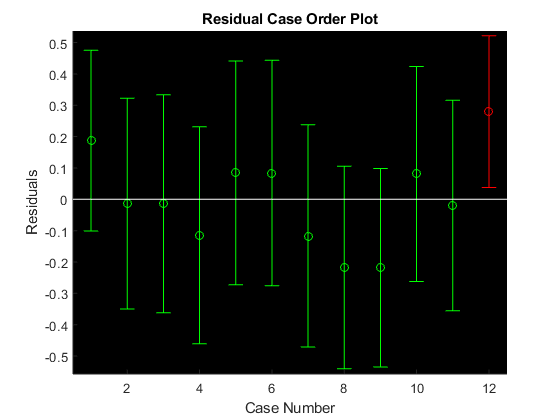

rcoplot(r,rint)

Gør det samme for de kvindelige data.

Lav en vektor med data for kvinder.

X_nat = data(13,1:12)';
n_nat = length(X_nat)

n_nat = 12

t = 1:12;

Vis den simple lineære regressionsmodel, hvor normalfordelte residualer antages.

% Levealder = Beta_0 + Beta_1 * Årstal efter 2000 + epsilon_i

Estimer de ukendte parametre i modellen: Skæring med y-aksen (Beta_0), hældning (Beta_1) og varians af fejlled.

X_reg = [[1:12]' ones(size(X_nat))];
[b, bint, r, rint, STATS] = regress(X_nat, X_reg);
Beta_0_x = b(2)

Beta_0_x = 78.8076

Beta_1_x = b(1)

Beta_1_x = 0.2476

% Varians af fejlled: SSE/df
% Findes med STATS(4)
sigma_e_squared_x = STATS(4)

sigma_e_squared_x = 0.0173

sigma_e_x = sqrt(sigma_e_squared_x)

sigma_e_x = 0.1316

Find R^2

% R^2 = STATS(1)
R2 = STATS(1)

R2 = 0.9806

Plot observationerne sammen med den estimerede regressionslinje

scatter(t,X_nat)
hold on
X_est = Beta_0_x + Beta_1_x * t_est;
plot(t_est,X_est)

Lav modeltjek for residualerne:

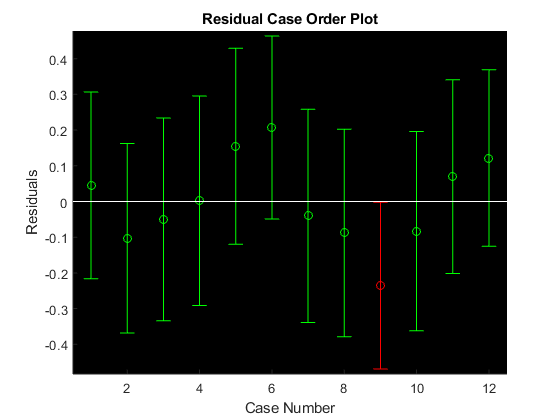

rcoplot(r,rint)

Del 6: Simpel lineær regression: inferens og forudsigelse

For den mandlige levealder:

Indiker fordelingen for estimatoren af regressionslinjens hældning. Udregn 90%-, 95%-, og 99%-konfidensintervaller for den ukendte hældning.

% Fordeling:
% Beta_hat ~ N (beta, sigma^2/s)
% Konfidensinterval:
% Beta_1^hat +- sqrt(sigma^2^hat/s_YY) * t_n-2,alpha/2
sYY = sum((Y_nat - mean(Y_nat)).^2)

sYY = 13.1867

Beta_1_up_Y = Beta_1_y + sqrt(sigma_e_squared_y / sYY) * tinv(1-alpha/2,n_nat-2)

Beta_1_up_Y =     0.3807    0.3990    0.4405


Beta_1_do_Y = Beta_1_y - sqrt(sigma_e_squared_y / sYY) * tinv(1-alpha/2,n_nat-2)

Beta_1_do_Y =     0.2207    0.2024    0.1609


Lav en forudsigelse for den forventede mandlige levetid i 2020. Udregn et 90%-, 95%- og 99%-konfidensinterval for denne forudsagte værdi i 2020.

Y_2020_y = Beta_0_y + Beta_1_y * (2020-2000)

Y_2020_y = 80.0261


% Konfidensinterval:
% Y_2020 +- sqrt(sigma_hat^2 * (1/n + (t_0 - t_bar)^2 / s_YY)) *
% t_n-2,alpha/2)
Y_2020_up = Y_2020_y + sqrt(sigma_e_squared_y * (1/n_nat + (2020-2000 - mean(t))^2 / sYY)) * tinv(1-alpha/2,n-2)

Y_2020_up =    81.1210   81.3773   81.9673


Y_2020_do = Y_2020_y - sqrt(sigma_e_squared_y * (1/n_nat + (2020-2000 - mean(t))^2 / sYY)) * tinv(1-alpha/2,n-2)

Y_2020_do =    78.9312   78.6749   78.0850


For den kvindelige levealder:

Indiker fordelingen for estimatoren af regressionslinjens hældning. Udregn 90%-, 95%-, og 99%-konfidensintervaller for den ukendte hældning.

% Fordeling:
% Beta_hat ~ N (beta, sigma^2/s)
% Konfidensinterval:
% Beta_1^hat +- sqrt(sigma^2^hat/s_XX) * t_n-2,alpha/2
sXX = sum((X_nat - mean(X_nat)).^2)

sXX = 8.9367

Beta_1_up_X = Beta_1_x + sqrt(sigma_e_squared_x / sXX) * tinv(1-alpha/2,n_nat-2)

Beta_1_up_X =     0.3274    0.3457    0.3871


Beta_1_do_X = Beta_1_x - sqrt(sigma_e_squared_x / sXX) * tinv(1-alpha/2,n_nat-2)

Beta_1_do_X =     0.1677    0.1494    0.1080


Lav en forudsigelse for den forventede mandlige levetid i 2020. Udregn et 90%-, 95%- og 99%-konfidensinterval for denne forudsagte værdi i 2020.

Y_2020_x = Beta_0_x + Beta_1_x * (2020-2000)

Y_2020_x = 83.7586


% Konfidensinterval:
% Y_2020 +- sqrt(sigma_hat^2 * (1/n + (t_0 - t_bar)^2 / s_YY)) *
% t_n-2,alpha/2)
Y_2020_up = Y_2020_x + sqrt(sigma_e_squared_x * (1/n_nat + (2020-2000 - mean(t))^2 / sXX)) * tinv(1-alpha/2,n-2)

Y_2020_up =    84.8506   85.1062   85.6946


Y_2020_do = Y_2020_x - sqrt(sigma_e_squared_x * (1/n_nat + (2020-2000 - mean(t))^2 / sXX)) * tinv(1-alpha/2,n-2)

Y_2020_do =    82.6666   82.4110   81.8226


Det ønskes at finde ud af, om den forventede levetid stiger lige meget for kvinder og mænd. Først skal dog testes, om varianserne er identiske. Lav en tosidet hypotesetest for at finde ud af dette. Definer en test-statistik, indiker dens fordeling, udregn test-statistikkens værdi, lave test med signifikansniveau 0.1, 0.05, 0.01. Udregn til sidst p-værdien. Hvis H0 ikke kan forkastes, udregnes et pooled estimat af variansen.

% Test-statistik:
% F0 = s_1^2 / s_2^2 ~ F_n1-1,n2-1
f0 = sigma_e_squared_y / sigma_e_squared_x

f0 = 1.4806

crit_val_up = finv(1-alpha/2,n_nat-1,n_nat-1)

crit_val_up =     2.8179    3.4737    5.3197


crit_val_do = finv(alpha/2,n_nat-1,n_nat-1)

crit_val_do =     0.3549    0.2879    0.1880



% Nulhypotesen, at de er identiske, kan altså ikke forkastes
% på noget signifikansniveau, hvorfor sigma_y = sigma_x.

p = 2 * (1 - fcdf(f0,n_nat-1,n_nat-1))

p = 0.5260

% Det samme bekræftes af p-værdien

% Pooled varians:
s_p_nat_squared = ((n_nat-1)*sigma_e_squared_y + (n_nat-1)*sigma_e_squared_x)/(n_nat+n_nat-2)

s_p_nat_squared = 0.0215

s_p_nat = sqrt(s_p_nat_squared)

s_p_nat = 0.1466

Test en tosidet hypotese, hvor nulhypotesen er, at hældningen for begge modeller er identisk. Definer først test-statistik og fordeling, udregn den derefter og lav test med signifikansniveau på 0.1, 0.05 og 0.01. Udregn p-værdien for testen.

% Test-statistik:
% T0 = (Beta_1_y - Beta_1_x) / sqrt (sigma_hat^2 (1 / sYY + 1 / sXX))
% Fordeling:
% (Beta_1_y - Beta_1_x) ~ N(Beta_1_y - Beta_1_x , sigma^2 (1 / sYY + 1 / sXX)
% Udregning:
t0 = (Beta_1_y - Beta_1_x) / sqrt (s_p_nat_squared * (1 / sYY + 1 / sXX))

t0 = 0.8366

crit_val_up = tinv(1-alpha/2,2*n_nat-4)

crit_val_up =     1.7247    2.0860    2.8453


% Dette viser, at nulhypotesen ikke forkastes ved noget
% signifikansniveau.

p = 2 * (1 - tcdf(t0,n_nat-1))

p = 0.4206

% Det samme viser p-værdien.

Del 7: Analysis of Variance, ANOVA

Der skal nu laves analyse over alle år fra alle regioner.

Lav først en matrix over alle oplysningerne for mænd. Tænk på denne matrix som inddelt (factored) i regioner med 12 observationer for hver faktor.

Y_ANOVA = data(2:12,1:12);
[a n] = size(Y_ANOVA)

a = 11

n = 12

N = a*n

N = 132

Test en tosidet hypotese om, at den ukendte middelværdi for alle faktorer er identiske. Gør dette ved at:

Udregn stikprøvegennemsnit for alle faktorer og i alt

Udregn en ANOVA-tabel med SS, df og S^2

Indiker en test-statistik og dens fordeling

Udregn test-statistikkens værdi

Udfør testen med signifikansniveau 0.1, 0.05 og 0.01.

Udregn p-værdien

Estimer tilbageværende parametre

Udregn og illustrer 95%-konfidensintervaller grafisk i én figur for alle faktorer

% Udregn gennemsnit
Y_bar_i = mean(Y_ANOVA,2);
Y_av = mean(Y_bar_i)

Y_av = 75.9886


% Lav tabellen med SST, SSW og SSB samt deres df og S^2
SST = sum(sum((Y_ANOVA - Y_av).^2))

SST = 253.5730

dfT = N-1;

ST_sqr = SST/dfT

ST_sqr = 1.9357

SSW = sum(sum((Y_ANOVA - Y_bar_i * ones(1,n)).^2))

SSW = 146.7392

dfW = N-a;
SW_sqr = SSW/dfW

SW_sqr = 1.2127


SSB = n * sum((Y_bar_i - Y_av).^2)

SSB = 106.8338

dfB = a-1;
SB_sqr = SSB/dfB

SB_sqr = 10.6834


% Udregn test-statistikken
t0 = SB_sqr/SW_sqr

t0 = 8.8094

crit_val = finv(1-alpha,a-1,N-a)

crit_val =     1.6519    1.9098    2.4708


% Dette viser, at nulhypotesen ikke kan forkastes

% Udregn p-værdien
p = 1 - fcdf(t0,a-1,N-a)

p = 9.6098e-11

% Denne viser det samme

mu_i_hat = Y_bar_i;
sigma_squared_hat = SW_sqr;

% CI_mu_i = mu_i + t_alpha/2,N-a * sqrt(sigma^2_hat / n)
CI_ANOVA_up = Y_bar_i + tinv(1-alpha/2,N-a) * sqrt(sigma_squared_hat/n)

CI_ANOVA_up =    74.2519   74.3544   74.5570
   76.5269   76.6294   76.8320
   77.3603   77.4627   77.6653
   76.7353   76.8377   77.0403
   76.9769   77.0794   77.2820
   75.2436   75.3460   75.5486
   76.5186   76.6210   76.8236
   76.8019   76.9044   77.1070
   77.2686   77.3710   77.5736
   77.1936   77.2960   77.4986


CI_ANOVA_do = Y_bar_i - tinv(1-alpha/2,N-a) * sqrt(sigma_squared_hat/n)

CI_ANOVA_do =    73.1981   73.0956   72.8930
   75.4731   75.3706   75.1680
   76.3064   76.2040   76.0014
   75.6814   75.5790   75.3764
   75.9231   75.8206   75.6180
   74.1897   74.0873   73.8847
   75.4647   75.3623   75.1597
   75.7481   75.6456   75.4430
   76.2147   76.1123   75.9097
   76.1397   76.0373   75.8347


Lav nu en matrix over alle oplysningerne for kvinder. Tænk på denne matrix som inddelt (factored) i regioner med 12 observationer for hver faktor.

X_ANOVA = data(14:24,1:12);
[a n] = size(X_ANOVA)

a = 11

n = 12

N = a*n

N = 132

Test en tosidet hypotese om, at den ukendte middelværdi for alle faktorer er identiske. Gør dette ved at:

Udregn stikprøvegennemsnit for alle faktorer og i alt

Udregn en ANOVA-tabel med SS, df og S^2

Indiker en test-statistik og dens fordeling

Udregn test-statistikkens værdi

Udfør testen med signifikansniveau 0.1, 0.05 og 0.01.

Udregn p-værdien

Estimer tilbageværende parametre

Udregn og illustrer 95%-konfidensintervaller grafisk i én figur for alle faktorer

% Udregn gennemsnit
X_bar_i = mean(X_ANOVA,2);
X_av = mean(X_bar_i)

X_av = 80.4167


% Lav tabellen med SST, SSW og SSB samt deres df og S^2
SST = sum(sum((X_ANOVA - X_av).^2))

SST = 145.2833

dfT = N-1;

ST_sqr = SST/dfT

ST_sqr = 1.1090

SSW = sum(sum((X_ANOVA - X_bar_i * ones(1,n)).^2))

SSW = 104.6850

dfW = N-a;
SW_sqr = SSW/dfW

SW_sqr = 0.8652


SSB = n * sum((X_bar_i - X_av).^2)

SSB = 40.5983

dfB = a-1;
SB_sqr = SSB/dfB

SB_sqr = 4.0598


% Udregn test-statistikken
t0 = SB_sqr/SW_sqr

t0 = 4.6926

crit_val = finv(1-alpha,a-1,N-a)

crit_val =     1.6519    1.9098    2.4708


% Dette viser, at nulhypotesen ikke kan forkastes

% Udregn p-værdien
p = 1 - fcdf(t0,a-1,N-a)

p = 1.1658e-05

% Denne viser det samme

mu_i_hat = X_bar_i;
sigma_squared_hat = SW_sqr;

% CI_mu_i = mu_i + t_alpha/2,N-a * sqrt(sigma^2_hat / n)
CI_ANOVAX_up = X_bar_i + tinv(1-alpha/2,N-a) * sqrt(sigma_squared_hat/n)

CI_ANOVAX_up =    79.5534   79.6399   79.8110
   80.8117   80.8983   81.0694
   81.4784   81.5649   81.7360
   80.9034   80.9899   81.1610
   81.0534   81.1399   81.3110
   80.0534   80.1399   80.3110
   81.1284   81.2149   81.3860
   81.1951   81.2816   81.4527
   81.4201   81.5066   81.6777
   81.1534   81.2399   81.4110


CI_ANOVAX_do = X_bar_i - tinv(1-alpha/2,N-a) * sqrt(sigma_squared_hat/n)

CI_ANOVAX_do =    78.6633   78.5767   78.4056
   79.9216   79.8351   79.6640
   80.5883   80.5017   80.3306
   80.0133   79.9267   79.7556
   80.1633   80.0767   79.9056
   79.1633   79.0767   78.9056
   80.2383   80.1517   79.9806
   80.3049   80.2184   80.0473
   80.5299   80.4434   80.2723
   80.2633   80.1767   80.0056


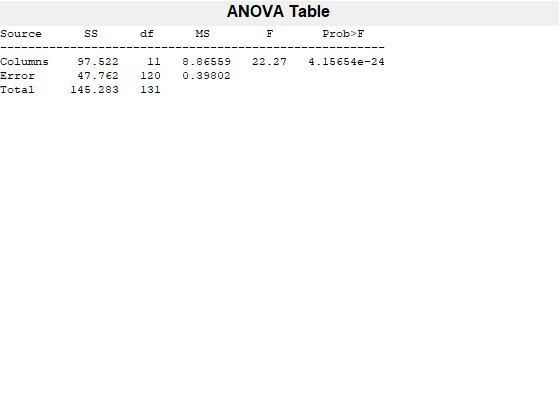

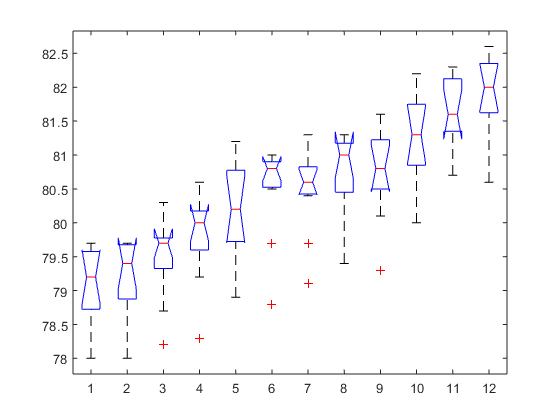

p = 4.1565e-24

tbl = 4×6 cell array
    {'Source' }    {'SS'      }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[ 97.5215]}    {[ 11]}    {[  8.8656]}    {[ 22.2745]}    {[4.1565e-24]}
    {'Error'  }    {[ 47.7618]}    {[120]}    {[  0.3980]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[145.2833]}    {[131]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [12×2 char]
         n: [11 11 11 11 11 11 11 11 11 11 11 11]
    source: 'anova1'
     means: [79.1000 79.2000 79.4909 79.8273 80.1909 80.5182 80.5091 80.7000 80.7545 81.2364 81.6182 81.8545]
        df: 120
         s: 0.6309



% ANOVA-FUNKTION
% ALTERNATIV
[p, tbl, stats] = anova1(X_ANOVA)